# Training a Deep Learning Model using AlexNet

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\melahi\Documents\MATLAB\Examples\R2021b\nnet\TransferLearningUsingGoogLeNetExample\CSV\params_2022_04_25__12_47_26.mat");

## Import Data

Import training and validation data.

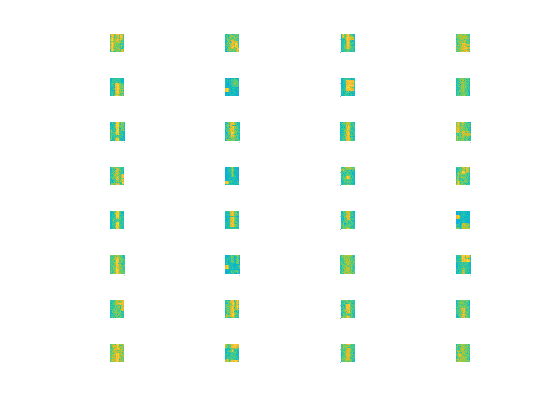

imdsTrain = imageDatastore("C:\Users\melahi\Documents\MATLAB\Examples\R2021b\nnet\TransferLearningUsingGoogLeNetExample\CSV\CSV","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);

figure
numImages = length(imdsTrain.Files);
perm = randperm(numImages,32);
for i = 1:32
    subplot(8,4,i);
    imshow(imdsTrain.Files{perm(i)});
    drawnow
end

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.0001,...
    "MaxEpochs",8,...
    "MiniBatchSize",4,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4],"Bias",trainingSetup.conv1.Bias,"Weights",trainingSetup.conv1.Weights)
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",trainingSetup.conv2.Bias,"Weights",trainingSetup.conv2.Weights)
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv3.Bias,"Weights",trainingSetup.conv3.Weights)
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv4.Bias,"Weights",trainingSetup.conv4.Weights)
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",trainingSetup.conv5.Bias,"Weights",trainingSetup.conv5.Weights)
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2,"Bias",trainingSetup.fc6.Bias,"Weights",trainingSetup.fc6.Weights)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2,"Bias",trainingSetup.fc7.Bias,"Weights",trainingSetup.fc7.Weights)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(5,"Name","fc","BiasLearnRateFactor",10,"WeightLearnRateFactor",10)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        0.00% |       23.08% |       5.4843 |       2.6711 |      1.0000e-04 |
|       1 |           5 |       00:00:04 |       25.00% |       23.08% |       5.7891 |       3.1067 |      1.0000e-04 |
|       2 |          10 |       00:00:06 |       75.00% |       23.08% |       1.1536 |       2.5598 |      1.0000e-04 |
|       2 |          15 |       00:00:09 |       50.00% |       30.77% |       2.9948 |   

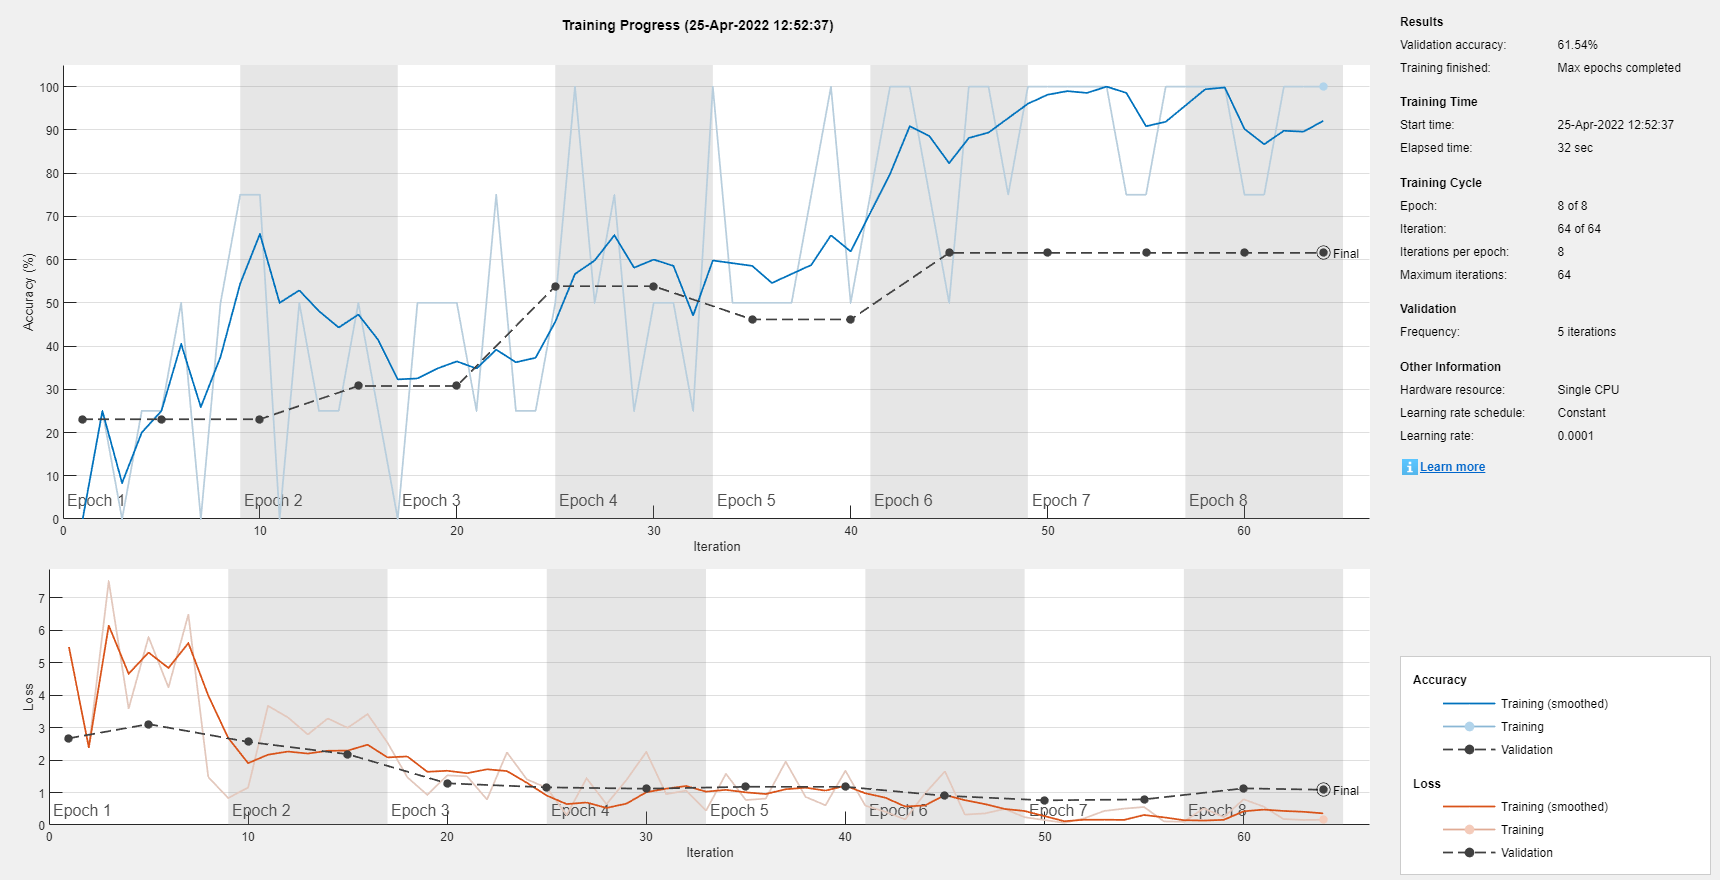

analyzeNetwork(net)
[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

## Confusion Chart

[YPred] = classify(net,augimdsValidation)
plotconfusion(imdsValidation.Labels,YPred)

## Classify Test Images

imagesAlexnet = imageDatastore(['C:\Users\melahi\Documents\' ...
    'MATLAB\Examples\R2021b\nnet\TransferLearningUsing' ...
    'GoogLeNetExample\Test\']);
for K = 1 : 30

    subplot(10,3,K);
    I_org = imread(imagesAlexnet.Files{K});
    I = imresize(I_org,[227,227]);
    [YPred,probs] = classify(net,I);
    imshow(I_org)
    label = YPred;
    title(string(label) + ", " + num2str(100*max(probs),3) + "%");
end
%save image
 userinput = input('Enter file name: ' , 's')

userinput = 'AlexNet classification'

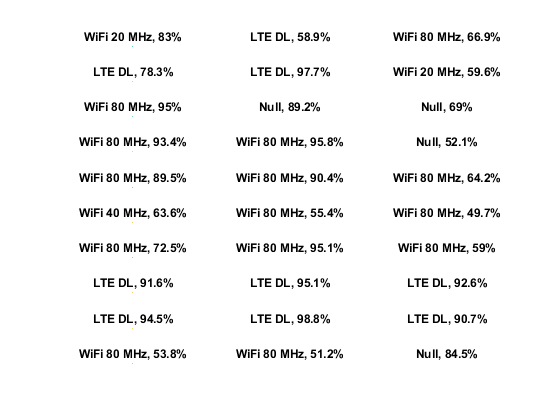

 filename = sprintf('%s', userinput);
 saveas(gcf, filename, 'png')